%Select experiment folder
FolderPath = uigetdir;
%Open raw .bin files
Binning = 1; %Bin IOI data
OpenIOI_NewSyst(FolderPath,Binning,3,0);

No Stimulations detected. Resting State experiment?


Analyze resting-state data to extract connectivity matrix and map specific metrics (FCC, ALFF, LDFC). First, perform signal preprocessing, including normalization (de-meaning and division by std) and bandpass filtering between 0.01 and 0.15 Hz.

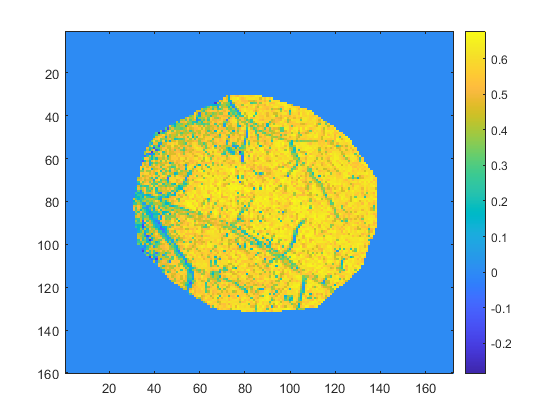

%Extract green reflectance images
[Green,GreenROI] = extractImMatrix(FolderPath,'green',1);
f = matfile([FolderPath filesep 'Data_green.mat']).Freq; %Acquisition frequency
%Normalize and filter signal
Green = (Green-mean(Green))./std(Green);
Green = bandpass(Green,[0.01 0.15],f);
%Compute weight matrix
W = corr(Green);
%Compute FCS
I = fcs(W,'zero');
%Compute ALFF
ALFF = oscPower(Green,[0.01 0.15],f);
%Map on orignal image
FCSimage = remapROI(I,GreenROI);
ALFFimage = remapROI(ALFF,GreenROI);
figure;
imagesc(FCSimage);
title('FCS');
c = colorbar;

c.Label = 'FCS';
figure;
imagesc(ALFFimage);
title('ALFF');
c = colorbar;
c.Label = 'ALFF';


